syms x y
z_total = 0;

positions = [0.75 -2.5; -0.25 1];
a = 1;
startPoint = [0.9 -1.5]

startPoint =     0.9000   -1.5000


endPoint = [-2 -0.5];
% z_total = makeDivot(positions(2,:),z_total,a);
% z_total = makeDivot(positions(1,:),z_total,a);
a = 0.5;
z_total = makeLineOfDivots(startPoint,endPoint,20,z_total,a);

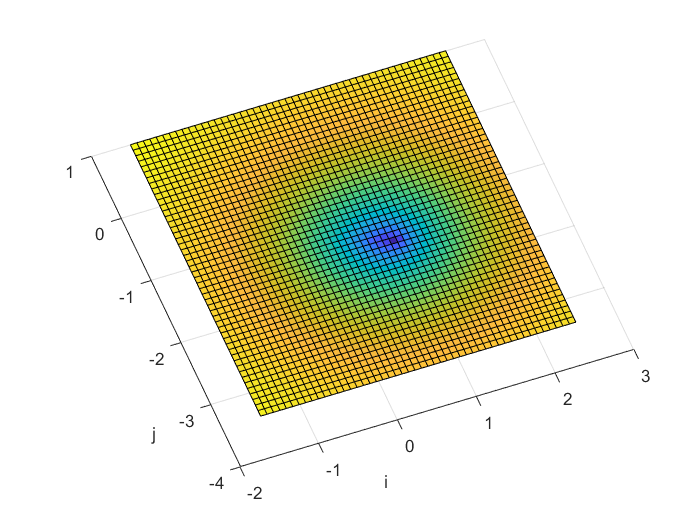

clf
[X,Y] = meshgrid(linspace(-1.5,2.5,50),linspace(-3.37,1,50));
Z = double(subs(z_total,{x,y},{X,Y}));
surf(X,Y,Z)
xlabel('i')
ylabel('j')
zlabel('k')